clearvars
close all
clc

#### read the WAVE file (*.wav)

% Fp sampling frequency in Hz
[y, Fp] = audioread('hw2_vuvuzela.wav');
% so that the samplig period is
T = 1/Fp; % [s]

#### listen to the original content

Ny = length(y);
sound(y, Fp);
pause(Ny/Fp + 1);

#### plot original signal in time

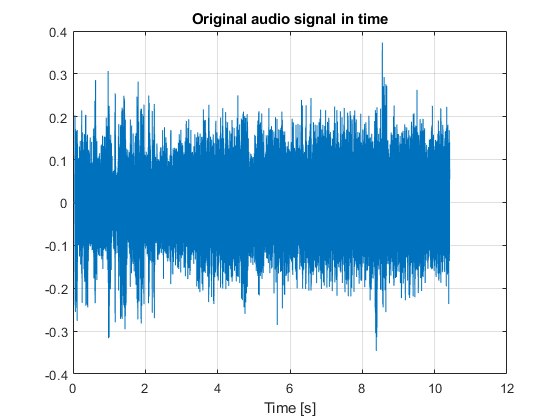

Ny = size(y,1);
ty = (0:Ny-1)*T;
plot(ty,y); grid; title("Original audio signal in time");
xlabel("Time [s]");

#### plot original signal in frequency

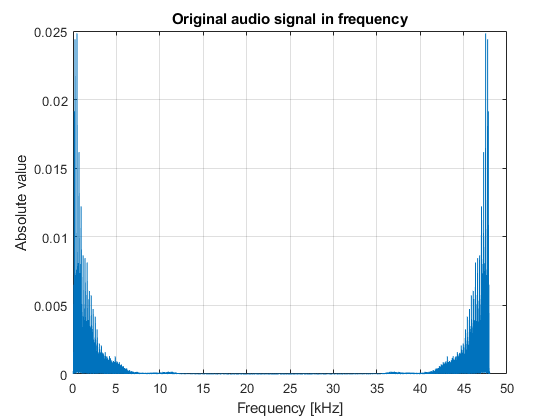

fy = (0:Ny-1)/(Ny*T);
Y = T*fft(y);
plot(fy/1e3,abs(Y)); 
grid; 
title("Original audio signal in frequency");
xlabel("Frequency [kHz]"); 
ylabel("Absolute value");

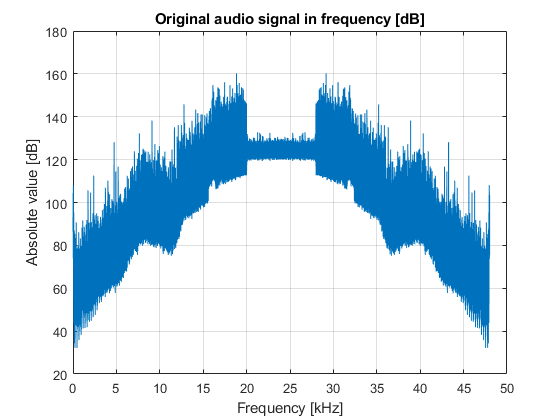

plot(fy/1e3,abs(20*log10(abs(Y)))); 
grid; 
xlabel("Frequency [kHz]");
ylabel("Absolute value [dB]");
title("Original audio signal in frequency [dB]");

#### IIR notch filters cascade

f0 = 235; % fundamental frequency of the vuvuzela sound (first hammonic)

N = 12; % remove the first N harmonics -> N IIR notch filters

f = 0:Fp/1000:Fp;  %% frq. vector
z = y;

for l=1:N
    
    theta = [l*f0*2*pi*T ; -l*f0*2*pi*T] ; % normalized frequencies
    r = 0.99; % trial and error
    zk = ( exp(1i.*theta) ).';
    pk = ( r*exp(1i.*theta) ).';
    H = ones(size(f));
    for k = 1:2
        num = (1 - zk(k)*exp(-1i*2*pi*f*T));
        num = num/(1-zk(k)); % normalization factor => H(0)=1
        den = (1 - pk(k)*exp(-1i*2*pi*f*T));
        den = den/(1-pk(k)); % normalization factor => H(0)=1
        H = H.*num./den;
    end
    b = [1 -2*cos(theta(1)) 1]; % numeretor coeff. poly in z^(-1)
    a = [1 -2*r*cos(theta(1)) r^2]; % denominator coeff. poly in z^(-1)
    z = filter(b,a,z); % filtering applied

end

#### plot N-th IIR notch filter

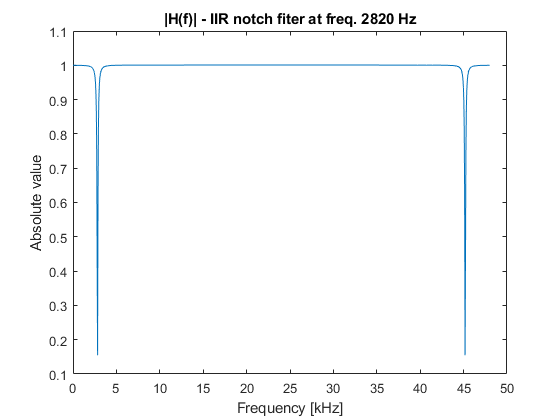

plot(f/1e3,abs(H)); 
xlabel("Frequency [kHz]"); 
ylabel("Absolute value"); 
title("|H(f)| - IIR notch fiter at freq. " + num2str(N*f0) +" Hz");

#### test before/after initial part

sound(y(1:4*Fp), Fp);
pause(4.5);
sound(z(1:4*Fp), Fp);
pause(5);

#### test before/after central part

sound(y(4*Fp:8*Fp), Fp);
pause(4.5);
sound(z(4*Fp:8*Fp), Fp);
pause(5);

#### test before/after final part

sound(y(8*Fp:end), Fp);
pause(3);
sound(z(8*Fp:end), Fp);

#### plot filtered signal in frequency

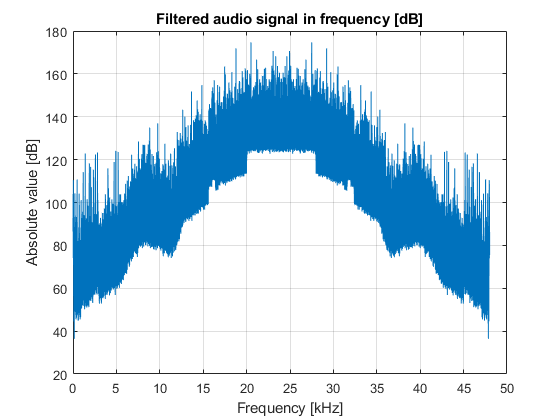

Nz = length(z);
fz = (0:Nz-1)/(Nz*T);
Z = T*fft(z);

plot(fz/1e3,abs(20*log10(abs(Z)))); 
grid; 
xlabel("Frequency [kHz]");
ylabel("Absolute value [dB]");
title("Filtered audio signal in frequency [dB]");

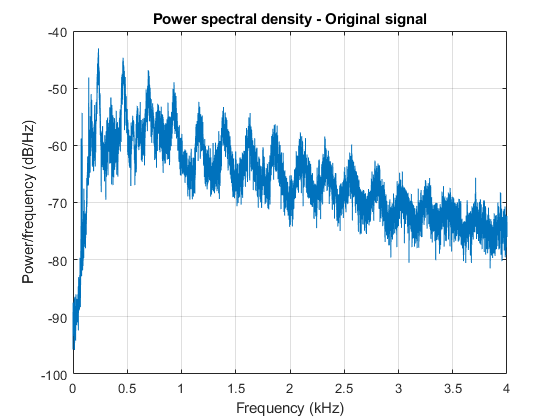

pwelch(y, [], [], [], Fp); xlim([0 4]); 
title("Power spectral density - Original signal");

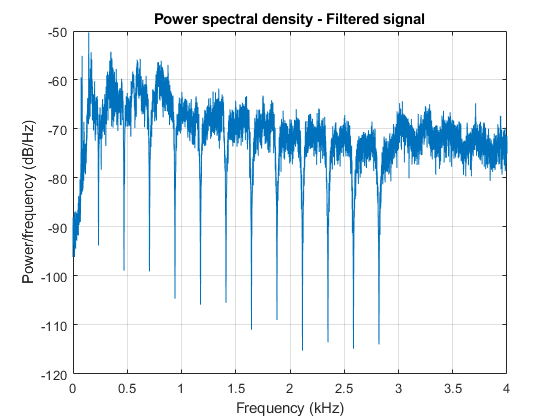

pwelch(z, [], [], [], Fp); xlim([0 4]); 
title("Power spectral density - Filtered signal");